#      Computational Electromagnetics 

##                                             Hw4

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/09/1       

clear; clc; close all;

## 4) Q:       3.49 

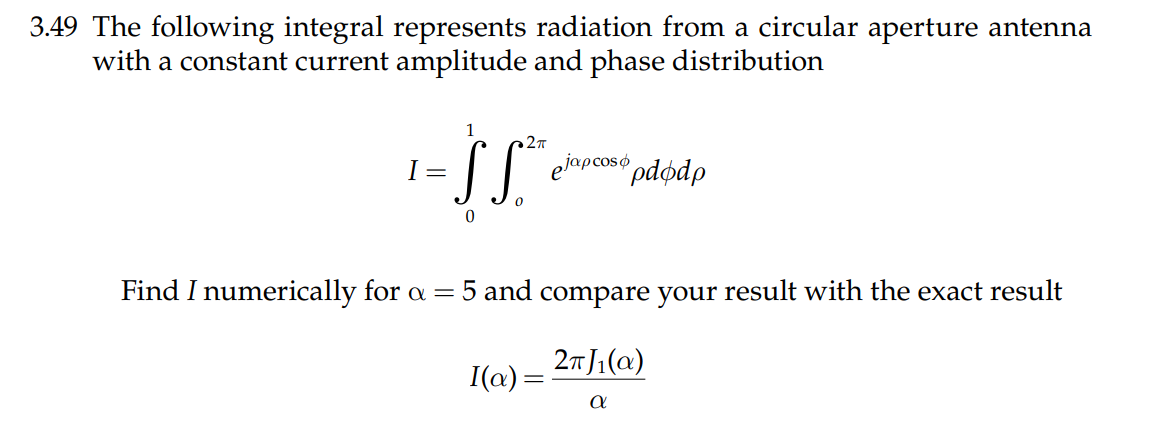

format long 

a = 0;
b = 2*pi;


alpha = 5;


## Trap:

h1 = pi/10;

p1 = 0;
p2 = 1;
Num_point  = 20;
P = linspace(p1,p2,Num_point);
Lp = length(P);

[Sum_Trap1,~] =  Mine_Trapezoidal_int(a,b,h1,P(1));
Sum_Trap1 = Sum_Trap1/2;
for j=1+1:Lp-1
[Result1_trap,~] = Mine_Trapezoidal_int(a,b,h1,P(j));
Sum_Trap1 = Sum_Trap1 + Result1_trap;
end

[Temp,~] =  Mine_Trapezoidal_int(a,b,h1,P(end));
Sum_Trap1 = Sum_Trap1 + 1/2*Temp;



## Gauss:


N = 5;
Sum_Gauss_tot = 0;
for j=1:Lp
Sum_Gauss = My_Gauss_Legendre_int(a,b,N,P(j));
Sum_Gauss_tot = Sum_Gauss + Sum_Gauss_tot;
end

## Symp:


n = 10 ;
Sum_Symp_tot =0;
for j=1:Lp
Sum_Symp = Symp_int_mine(a,b,n,P(j));
Sum_Symp_tot = Sum_Symp + Sum_Symp_tot;
end


## Compare:


Exact_Sol = 2*pi*besselj(1,alpha)/alpha;

Errors = [Sum_Trap1 , Sum_Gauss_tot , Sum_Symp_tot] - Exact_Sol;

disp(Errors)

  Columns 1 through 2

 -7.396985545174365 + 0.000000000000000i 13.504879161977287 +13.613822818796239i

  Column 3

 -7.996813076123102 - 4.536279147336143i



% There is Too much Errorv-- >>> Let's Increase the number of Points!


## Trap:

Increased Point from 20 to 100 each!


h1 = (b-a)/100;

p1 = 0;
p2 = 1;
Num_point  = 100;
P = linspace(p1,p2,Num_point);
Lp = length(P);

[Sum_Trap2,~] =  Mine_Trapezoidal_int(a,b,h1,P(1));
Sum_Trap2 = Sum_Trap2/2;
for j=1+1:Lp-1
[Result1_trap,~] = Mine_Trapezoidal_int(a,b,h1,P(j));
Sum_Trap2 = Sum_Trap2 + Result1_trap;
end

[Temp,~] =  Mine_Trapezoidal_int(a,b,h1,P(end));
Sum_Trap2 = Sum_Trap2 + 1/2*Temp;


## Gauss:


N = 20;
Sum_Gauss_tot2 = 0;
for j=1:Lp
Sum_Gauss = My_Gauss_Legendre_int(a,b,N,P(j));
Sum_Gauss_tot2 = Sum_Gauss + Sum_Gauss_tot2;
end


## Symp:

Increased Number of Points:


n = 50 ;
Sum_Symp_tot2 =0;

for j=1:Lp
Sum_Symp = Symp_int_mine(a,b,n,P(j));
Sum_Symp_tot2 = Sum_Symp + Sum_Symp_tot2;
end

This is Funny! --> Every 3 Methods converge to -41 whereas the exact solutions which is -0.4116 !!!!  -- >>>>  There shall be something here wrong!

I seem to be unable to track the mistake but functions are working fine!

--- >>>> I found the problem!  --- >>> I was not multiplying the second stepsize to the function value! --- >>> which is exactly 0.01 ! -- >>>

meaning the integrals converged successfully!

delta_p = P(2)-P(1);
Sum_Symp_tot2 = Sum_Symp_tot2 * delta_p;
Sum_Gauss_tot2 = Sum_Gauss_tot2  * delta_p; 
Sum_Trap2 = Sum_Trap2 * delta_p;



## Compare:


Exact_Sol = 2*pi*besselj(1,alpha)/alpha;

Errors2 = [Sum_Trap2 , Sum_Gauss_tot2 , Sum_Symp_tot2] - Exact_Sol;

disp(Errors2)

  Columns 1 through 2

  0.000024590201999 - 0.000000000000000i -0.005615718957632 - 0.000002361478280i

  Column 3

 -0.005611134162268 - 0.000000000000000i



%  :))))))   

function [Result_1,h1] = Mine_Trapezoidal_int(a,b,h,P)

h1=h;
% x0=a:h/5:b;

L=ceil((b-a)/h);
y=zeros(L+1,1);

alpha =5;

syms x

f(x)=  exp(1j*alpha*P*cos(x))*P ;

    try
    for i=1:L+1
       if(i==1) 
       y(i)=1/2*double(f(a+(i-1)*h));
       elseif(i==L+1)
           y(i)=1/2*double(f(a+(i-1)*h));
       else
           y(i)=double(f(a+(i-1)*h));
       end
    end
    catch
        % continue
    end
   
Result_1=h*sum(y,'all'); % Zoonagheyi Solution

end




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




function Result = Symp_int_mine(a,b,n,P)
h=((b-a)/n);
y=zeros(n,1);

alpha=5;

syms x
f(x)=  exp(1j*alpha*P*cos(x))*P ;

try
for i=1:n+1
    if((i==1)||(i==n+1))
        y(i)= f(a+(i-1)*h);
    elseif(mod(i,2)==0)
        y(i)= 4*f(a+(i-1)*h);
    else
        y(i)= 2*f(a+(i-1)*h);
    end
end
catch
    %continue
end
Result=h/3*sum(y,'all');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Sum = My_Gauss_Legendre_int(a,b,N,P)

alpha=5;

syms x
f(x)=  exp(1j*alpha*P*cos(x))*P ;
% g(x)=(b-a)/2*f(1/2*((b-a)*x+(b-a)));

% Legendre Polynomials  --> Usable in [-1,1]
% P_m = zeros(1,N);
P_m(1) = sym(1) ;
P_m(2) = x;
for m=2:N-1

P_m(m+1) = (2*(m-1)+1)/((m-1)+1)*x*P_m(m) - ((m-1))/((m-1)+1)*P_m(m-1)  ; 

end

X_roots = cell(1,N);
for m = 1:N
roots = vpasolve(legendreP(m,x) == 0);
X_roots{1,m} = double(roots);
end

%% Find H for m = N;
H = zeros(1,N);
p_roots  = X_roots{1,N};
Leg_polys(x) = P_m(1,N);
Sum = 0;

for m=1:N
    
    H(1,m) = 2*(1-p_roots(m)^2) / ( ( N )^2 *  ( double(Leg_polys(p_roots(m))) )^2  );

    if (   (b-a)/2*p_roots(m) + (b+a)/2 == 0 )
    Sum  = Sum +0; % Function Value at 0 is 0!    
    else
    Sum = Sum + H(1,m)*double(  f( (b-a)/2*p_roots(m) + (b+a)/2   )   ) ;
    end

end

Sum  = (b-a)/2 * Sum;




end





